clear
addpath DrivingCodeAndData\
%load DrivingCodeAndData\EncoderDriving1.mat %small loops
%load DrivingCodeAndData\EncoderDriving2.mat %slightly larger loops
%load DrivingCodeAndData\EncoderDriving3.mat %drive into a wall intentionally
%load DrivingCodeAndData\EncoderDriving4.mat %testing a potential conflict with max velocity
%load DrivingCodeAndData\EncoderDriving5.mat %15 Hz
load DrivingCodeAndData\EncoderDriving6.mat %30 Hz
Robot.x_real = storage(:,1);
Robot.y_real = storage(:,2);
Robot.theta_real = storage(:,3);
Robot.VL_Set = storage(:,4);
Robot.VR_Set = storage(:,5);
simulation_timer = storage(:,6);
Encoders.L = storage(:,7);
Encoders.R = storage(:,8);

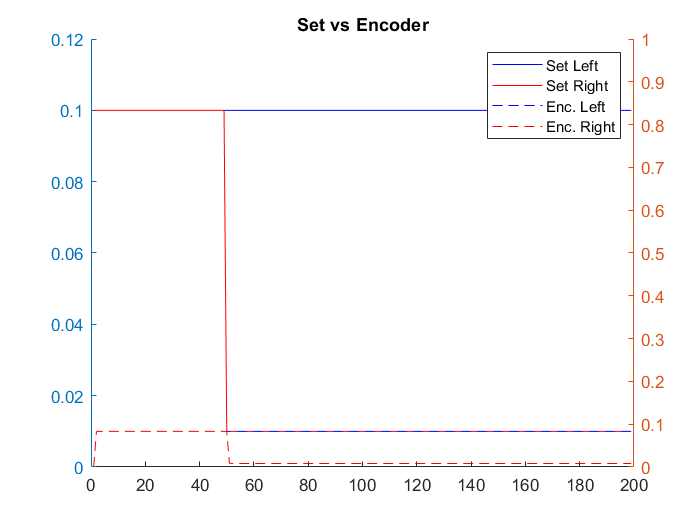

%offset encoder powers so they align with things
Robot.VL_Encoder = [0;diff(Encoders.L)];
Robot.VR_Encoder = [0;diff(Encoders.R)];

clf; hold on;
yyaxis left
plot(Robot.VL_Set,"b-","DisplayName","Set Left");
plot(Robot.VR_Set,"r-","DisplayName","Set Right");
plot(Robot.VL_Encoder,"b--","DisplayName","Enc. Left");
plot(Robot.VR_Encoder,"r--","DisplayName","Enc. Right");
title("Set vs Encoder"); legend()

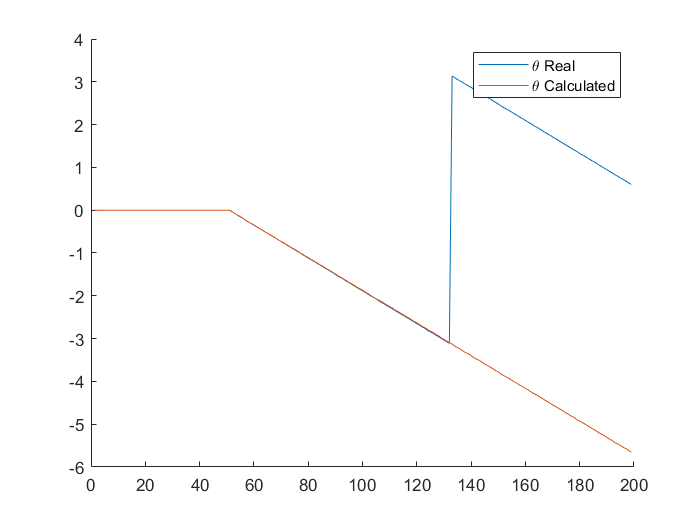

d_time = [0;diff(simulation_timer)]; %offset time so it aligns, also make time be the change from one cycle to the next
max_steps = size(storage,1); %how many cycles did the program go through?

%setup parameters of robot
wheel_spacing = 0.235;
wheel_radius = 0.070/2;

%initialize arrays with zeros
linear_velocity = zeros((max_steps),1);
angular_velocity = zeros((max_steps),1);
Robot.theta_calculated = zeros((max_steps),1);
Robot.x_calculated = zeros((max_steps),1);
Robot.y_calculated = zeros((max_steps),1);

%initial values for position
% yes I am using the data I pulled from the simulator, this is just because
% not every dataset aligns
Robot.x_calculated(1) = Robot.x_real(1);
Robot.y_calculated(1) = Robot.y_real(1);
Robot.theta_calculated(1) = Robot.theta_real(1);


%scalar values for linear and angular velocity
% linear_velocity_scalar = 1.021; %for 3 Hz
% angular_velocity_scalar = 1.486; %for 3 Hz

% linear_velocity_scalar = 1.06; %for 15 Hz
% angular_velocity_scalar = 5; %for 15 Hz

linear_velocity_scalar = 1; %for 30 Hz
angular_velocity_scalar = 9.97; %for 30 Hz

%calculate linear and angular velocity using the encoder data
linear_velocity = [0;linear_velocity_scalar.*((Robot.VR_Encoder+Robot.VL_Encoder)./2)];
angular_velocity = [0;angular_velocity_scalar.*((Robot.VR_Encoder-Robot.VL_Encoder)./(wheel_spacing))]; %may be * 2/wheel_spacing or * wheel_spacing/2

%calculate theta
for n = [2:max_steps]
    Robot.theta_calculated(n) = Robot.theta_calculated(n-1)+angular_velocity(n)*d_time(n);
end

clf; hold on;
plot((Robot.theta_real),"DisplayName","\theta Real")
plot((Robot.theta_calculated),"DisplayName","\theta Calculated")
legend()

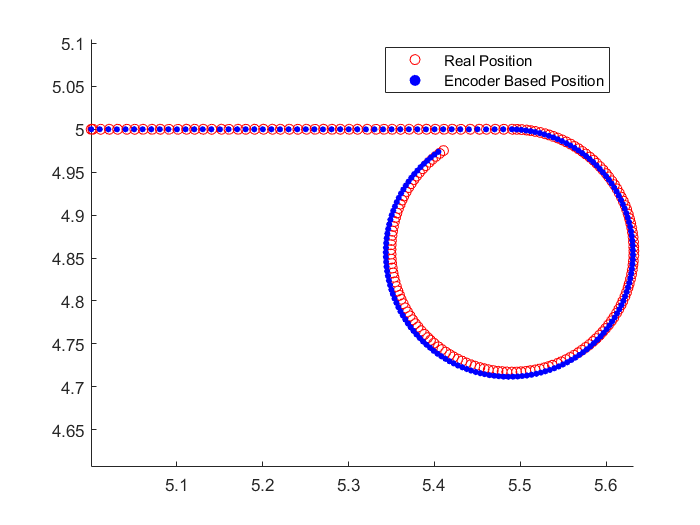


%calculate x y position
for n = [2:max_steps]
    Robot.x_calculated(n) = Robot.x_calculated(n-1)+linear_velocity(n)*(cos(Robot.theta_calculated(n)));
    Robot.y_calculated(n) = Robot.y_calculated(n-1)+linear_velocity(n)*(sin(Robot.theta_calculated(n)));
end

%plot stuff
clf; hold on; axis equal
scatter(Robot.x_real,Robot.y_real,"ro","DisplayName","Real Position")
scatter(Robot.x_calculated,Robot.y_calculated,10,"bo","DisplayName","Encoder Based Position","MarkerFaceColor","b"); legend("Location","best")

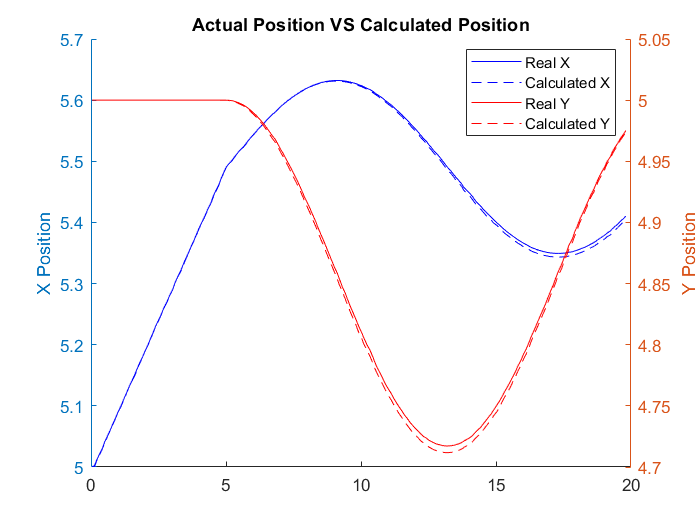

clf; hold on;
yyaxis left
plot(simulation_timer,Robot.x_real,"b-","DisplayName","Real X")
plot(simulation_timer,Robot.x_calculated,"b--","DisplayName","Calculated X")
ylabel("X Position")
yyaxis right
plot(simulation_timer,Robot.y_real,"r-","DisplayName","Real Y")
plot(simulation_timer,Robot.y_calculated,"r--","DisplayName","Calculated Y")
ylabel("Y Position")
legend("location","best"); title("Actual Position VS Calculated Position");

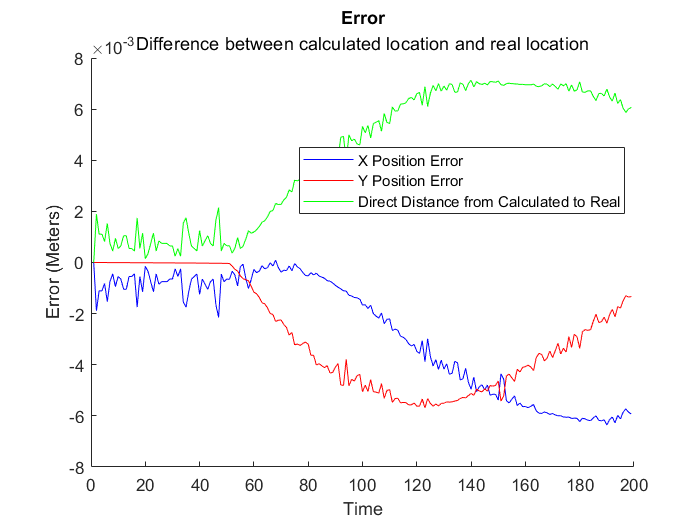

clf; hold on;
title("Error"); subtitle("Difference between calculated location and real location")
x_error = Robot.x_calculated-Robot.x_real; %difference between real and calculated
y_error = Robot.y_calculated-Robot.y_real; %difference between real and calculated
shortest_distance = sqrt(x_error.^2+y_error.^2); %use pythagorean theorem to calculate the direct distance from the real points to the calculated ones
plot(x_error,"b-","DisplayName","X Position Error")
plot(y_error,"r-","DisplayName","Y Position Error")
plot(shortest_distance,"g-","DisplayName","Direct Distance from Calculated to Real")
xlabel("Time"); ylabel("Error (Meters)"); legend("location","best");

disp({['Avg X Error: ',num2str(mean(x_error)),'. Avg Y Error: ',num2str(mean(y_error)),'. Avg Direct Distance Error: ',num2str(mean(shortest_distance))];['Max X Error: ',num2str(max(abs(x_error))),'. Max Y Error: ',num2str(max(abs(y_error))),'. Max Direct Distance Error: ',num2str(max(abs(shortest_distance)))]});

    {'Avg X Error: -0.0027046. Avg Y Error: -0.0027972. Avg Direct Distance Error: 0.0042118'}
    {'Max X Error: 0.0063562. Max Y Error: 0.0056825. Max Direct Distance Error: 0.0071305'  }

